# Live Demo: Infectious disease spread in a neighborhood-level metapopulation model

### **6.336 Final Project**

**Suleeporn Yui Sujichantararat, Georgia Thomas, Jason Zhang     GROUP ID: DISEASE**

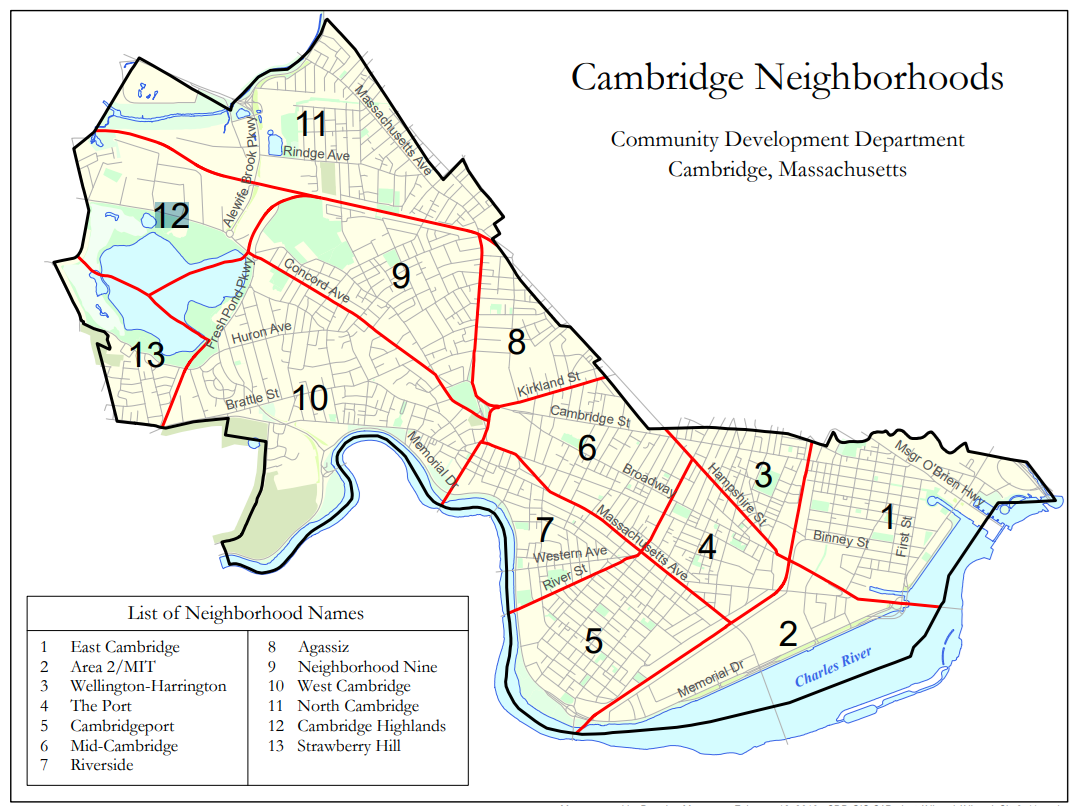

## **SEIR model, single neighborhood**

- One population with a single infected person, simulate from 0 to 100 days

- $\theta_{ij}$ = 0, no travel/commute from or to any other neighborhood

- $x_{sim,1}$ contains  $[S_1, E_1, I_1, R_1 ...S_P, E_P, I_P, R_P ]^T$ for all time

- $y_{sim,1}$ contains  $[\sum_{i=1}^{P} S_i,\;\;\sum_{i=1}^{P} E_i,\;\; \sum_{i=1}^{P} I_i,\;\;\sum_{i=1}^{P} R_i]^T$ for all time

% Simulation parameters
dt = 0.5;
numNeighborhoods = 1;
cases = {'noTravel','noMeasures','cutOffMultiple'};
stateInitType = {'singleInfectedAll', 'MIToutbreak'};

% Simulation
[ySim1, xSim1] = SimSEIR(numNeighborhoods, cases{1}, stateInitType{1}, dt);

Show the proportions of individuals in SEIR vs. time. Note that $y_{sim,1} = x_{sim,1}$ for the single neighborhood case.

Animate the SEIR trajectories.

f1 = plotSEIRProp(ySim1,xSim1,dt);
animationSpeed = 3;
% pause;
f2 = animateSEIR(ySim1,animationSpeed);

Calculate the maximum number of exposed and infected.

[maxEsim1, maxIsim1] = getMaxVals(xSim1);
fprintf('Sim 1: Max E = %5f \t Max I = %5f\n', maxEsim1, maxIsim1);

##  SEIR metapopulation (multiple neighborhoods) model, with travel

- 13 neighborhoods, single infected person in Neighborhood 2 (MIT)

- $\theta_{ij} \ne 0$, unrestricted travel/commute between neighborhoods

- Corresponds to little public health intervention

% Simulation parameters
numNeighborhoods = 13;

% Simulation
[ySim2, xSim2, pSim2] = SimSEIR(numNeighborhoods, cases{2}, stateInitType{2}, dt);

Show the proportions of individuals in SEIR vs. time.

close all;
f3 = plotSEIRProp(ySim2,xSim2,dt);

Animate the SEIR trajectories.

animationSpeed = 3;
% pause();
 f4 = animateSEIR(ySim2,animationSpeed);

Visualize  geographic spread.

% pause();
plotEdges = false;
geovisSEIR(xSim2,dt,pSim2,plotEdges);

Calculate the maximum number of exposed and infected.

[maxEsim2, maxIsim2] = getMaxVals(ySim2);
fprintf('Sim 2: Max E = %5f \t Max I = %5f\n', maxEsim2, maxIsim2);

##  SEIR metapopulation model, with travel and neighborhood quarantine

- 12 neighborhoods, single infected person in Neighborhood 2

- $\theta_{ij} \ne 0$ except for neighborhoods 1,2 4, and 5, which are isolated (no travel/commute from or to any other neighborhood)

- Equivalent to zeroing out the 1st, 2nd, and 5th rows & columns in $\theta_{ij}$

- We hope to see a flattened curve for I.

% Simulation parameters
numNeighborhoods = 13;

% Simulation
[ySim3, xSim3, pSim3] = SimSEIR(numNeighborhoods, cases{3}, stateInitType{2},dt);

Show the proportions of individuals in SEIR vs. time.

close all;
f5 = plotSEIRProp(ySim3,xSim3,dt);

Animate the SEIR trajectories.

% pause();
animationSpeed = 3;
f6 = animateSEIR(ySim3,animationSpeed);

Visualize  geographic spread.

% pause();
plotEdges = false;
geovisSEIR(xSim3, dt, pSim3, plotEdges);

Calculate the maximum number of exposed and infected.

[maxEsim3, maxIsim3] = getMaxVals(ySim3);
fprintf('Sim 3: Max E = %5f \t Max I = %5f\n', maxEsim3, maxIsim3);

Check the prtoportion in recovered at end of simulation.

plot(sum(ySim1,1))
plot(ySim1(4,:)./sum(ySim1,1))

plot(sum(ySim2,1))
plot(ySim2(4,:)./sum(ySim3,1))

plot(sum(ySim3,1))
plot(ySim3(4,:)./sum(ySim3,1))